# Sistemas Realimentados - 2023/1

## Nome: William Fernandes Pereira

## Data de entrega limite: 4/4

## Trabalho 1 

**Referências para ler para este trabalho**

- [Manual rápido do Matlab](https://drive.google.com/file/d/1_mXyft7ynFmkxGnCyx7BV8VyOKyIx9tj/view?usp=share_link)

- [Resposta transitória e estacionária](https://drive.google.com/file/d/19GToHEkcvTon0UK2nOmi1_l0k5dx3YIJ/view?usp=share_link)

## Resposta transitória e de regime de sistemas dinâmicos

Definições:

datetime('now')

ans = datetime
   05-Apr-2023 15:25:25


I=29;
[tau,zeta,wn,teta,p] = init(I);
g1=tf(p,[tau 1]);
g2=tf(wn^2,[1 2*zeta*wn wn^2]);
g0=tf(p,[tau 1],'InputDelay',teta);
g3=tf(p^3,poly(-[p p p]));
[y0,t0]=step(g0);
[y1,t1]=step(g1);
[y2,t2]=step(g2);


1) Obtenha a constante de tempo, o tempo de estabilização e o ganho do sistema cuja resposta ao degrau unitário é mostrada na figura 1.

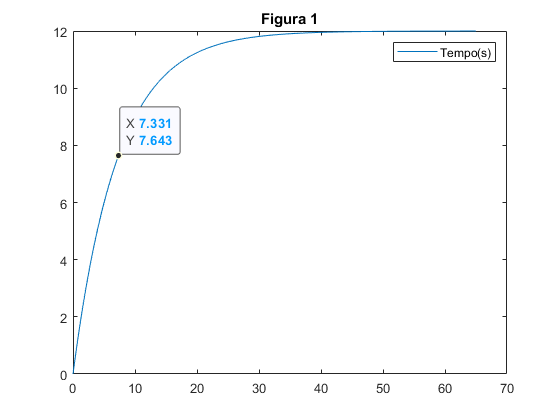

figure;
plot(t1,y1);legend('Tempo(s)');title('Figura 1');

xlim('auto')
ylim('auto')
ax = gca;
chart = ax.Children(1);
datatip(chart,7.20,7.56);

Resposta:

**- Constante de tempo:**

Temos que a constante de tempo é obtida analisando o gráfico e observando o valor em regime, sendo o tempo em que a saída atinja 63% do valor de regime. Como na figura 1 o valor em regime é 12, temos que 63% do valor em regime é 7.56. Então, analisando o gráfico, temos que **T = 7.2s**.

**- Tempo de estabilização:**

    Podemos aproximar o tempo de estabilização como sendo 4T, ou seja, ts = 4 * 7.2s ∴ **ts = 28.8s.**

**- Ganho:**

    O ganho é a relação entre entrada e saída, saída = k * entrada. Sabemos que a entrada é um degrau unitário e a saída, em regime, é 12. 

Então 12 = k * 1 ∴ o ganho é **K = 12**. 

2) Obtenha a constante de tempo, o tempo morto, o tempo de estabilização e o ganho do sistema cuja resposta degrau unitário é mostrada na figura 2.

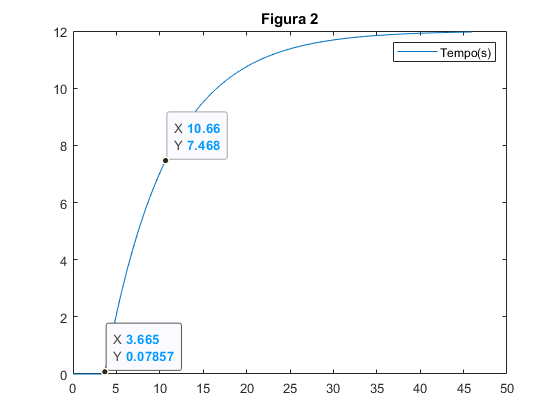

figure;
plot(t0,y0);legend('Tempo(s)');title('Figura 2');
ax = gca;
chart = ax.Children(1);
datatip(chart,10.66,7.468);
ax = gca;
chart = ax.Children(1);
datatip(chart,3.665,0.07857);   

Resposta:

**- Constante de tempo **

    Assim como na questão anterior, o valor em regime é 12 e 63% do valor em regime também é 7.56. Mas nesse caso temos um atraso ou ponto morto de 3.5s, assim, podemos obter a constante de tempo sendo T = 10.8s - 3.6s ∴ **T = 7.2s.**

**- Tempo morto**

    Analisando o gráfico, podemos obter o tempo morto sendo de 3.6s.

**- Tempo de estabilização**

    Podemos aproximar o tempo de estabilização como sendo 4T, ou seja, ts = 4 * 7.2s ∴ **ts = 28.8s.**

**- Ganho**

    O ganho é a relação entre entrada e saída, saída = k * entrada. Sabemos que a entrada é um degrau unitário e a saída, em regime, é 12. 

Então 12 = k * 1 ∴ o ganho é **K = 12**.

3) Obtenha o tempo de subida, a sobre-elevação (0 a 100%), o tempo de estabilização, o ganho do sistema cuja resposta ao degrau unitário é mostrada na figura 3.

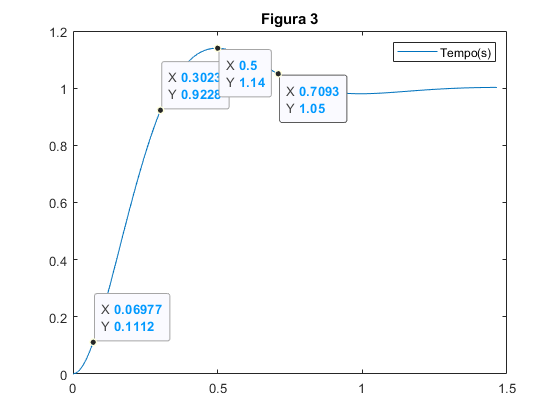

figure;
plot(t2,y2);legend('Tempo(s)');title('Figura 3');

ax = gca;
chart = ax.Children(1);
datatip(chart,0.3023,0.9228);

ax = gca;
chart = ax.Children(1);
datatip(chart,0.06977,0.1112);

ax = gca;
chart = ax.Children(1);
datatip(chart,0.5,1.14);

ax = gca;
chart = ax.Children(1);
datatip(chart,0.7093,1.05);

Resposta:

**- Tempo de subida**

    O tempo de subida é o tempo que leva para a resposta ir de 10% para 90% do valor em regime. Pelo gráfico, vemos que o valor em regime é de 1, então 10% é 0.1 e 90% é 0.9. Também pelo gráfico, podemos dizer que t(0.1) = 0.06s e t(0.9) = .0.30s. 

 Temos que tr = t(0.9) - t(0.1) = 0.30s - 0.06s ∴ **tr = 0.24s**

**- Sobre-elevação (0 a 100%)**

    A sobre-elevação é a diferença entre o valor máximo e o valor em regime da resposta, em porcentagem. Do gráfico, obtemos que o valor máximo da resposta é de 1.14 e já sabemos que o valor em regime é 1. 

Assim, UP = $\frac{V_{\textrm{máx}} -V_{\textrm{rp}} }{V_{\textrm{rp}} }$  =  $\frac{1\ldotp 14-1}{1}$  = 0.14 ∴ **UP = 14%**

**- Tempo de estabilização**

    Em sistemas de 2° ordem, o tempo de estabilização é o tempo necessário para que a resposta se estabilize dentro de uma faixa específica, nesse caso de 5% em torno do valor final. Como o valor final da nossa resposta é 1, a faixa está entre 0.95 e 1.05. 

Analisando o gráfico, temos que **ts = 0.70s** 

**- Ganho**

    O ganho é a relação entre entrada e saída, saída = k * entrada. Sabemos que a entrada é um degrau unitário e a saída, em regime, é 1. 

Então 1 = k * 1 ∴ o ganho é **K = 1**.

4) Na figura 4  mostra-se o efeito do amortecimento $\zeta$na sobreelevação (UP) e tempo de estabilização (ts).  A relação UP com $\zeta$ é dada por $\textrm{UP}=100e^{-\zeta \pi /\sqrt{1-\zeta^2 }}$, e a relação de ts com $\zeta$é dada aproximadamente por $\textrm{ts}=\frac{4}{\zeta \omega_n }$, $0<\zeta <0\ldotp 9$.

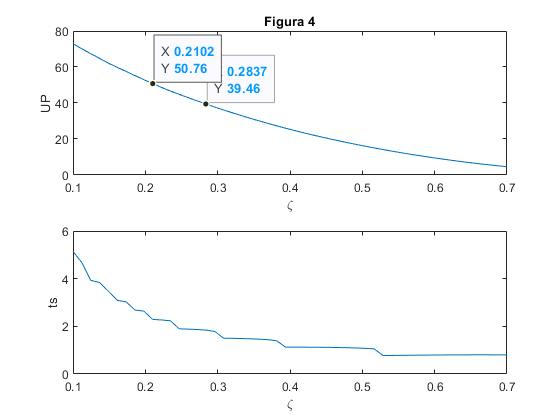

z=linspace(0.1,0.7,50);
ts=[];UP=[];
for i=1:50
    m=tf(wn^2,[1 2*z(i)*wn wn^2]);
    S=stepinfo(m);
    ts(i,1)=S.SettlingTime;
    UP(i,1)=S.Overshoot;
end
figure;
subplot(211);plot(z,UP);xlabel('\zeta');ylabel('UP');title('Figura 4')
subplot(212);plot(z,ts);xlabel('\zeta');ylabel('ts')

subplot(2,1,1)
ax = gca;
chart = ax.Children(1);
datatip(chart,0.2837,39.46);

subplot(2,1,1)
ax = gca;
chart = ax.Children(1);
datatip(chart,0.2102,50.76);

Explique, observando as figuras, como $\zeta$se relaciona com UP e ts, e obtenha a faixa de valores de $\zeta$para os quais a sobre-elevação esteja entre 40 e 50%, verificando a que faixa de valores de tempo de estabelecimento isso corresponde.

Resposta:

Observando a figura 4, podemos observar que quanto maior é o amortecimento, menores são a sobre-elevação e o tempo de estabelecimento. O que faz muito sentido, visto que quanto mais amortecido é um sistema, menor será a sobre-elevação e, com baixa sobre-elevação, o tempo para que o sistema atinja o seu valor de regime será menor.

Do gráfico, temos que o intervalo de $\zeta$ para que a sobre-elevação esteja entre 40% e 50% é **0.21 < **$\zeta$** < 0.28**, nessa faixa de valores, o tempo de estabelecimento se encontra entre **1.84 < ts < 2.29.**

Seja a localização do par de polos complexos de uma FT de um protótipo de segunda ordem mostrada na figura 5.

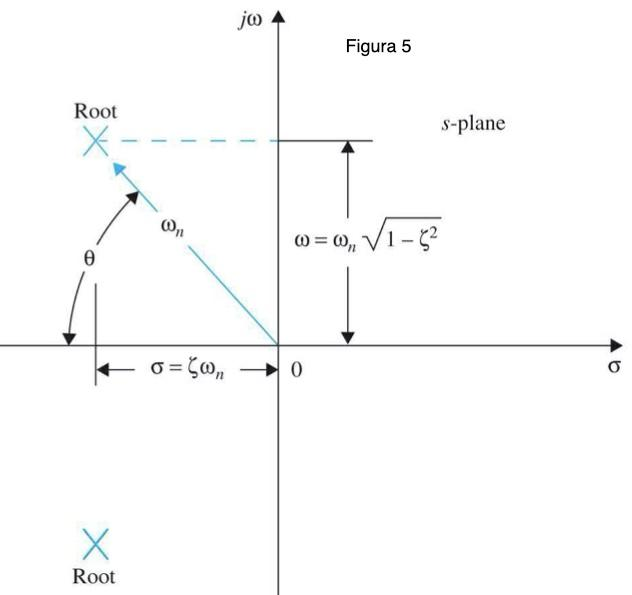

5) Use a expressão que relaciona de ts com $\zeta$e $\omega_n$ para explicar onde devem estar os polos de malha fechada para um menor tempo de estabilização. 

Resposta:

Sabendo que $\textrm{ts}=\frac{4}{\zeta \omega_n }$ e que a distância, no eixo $\sigma$, é $\sigma$ = $\zeta \omega_{\mathit{\mathbf{n}}}$, podemos afirmar que ts é inversamente propocional à distância entre os polos e o eixo j$\omega$, ou seja, os pólos devem estar à **esquerda**  do eixo j$\omega \;$(pois se estivessem à direita, o sistema seria instável e não estabilizaria) e **quanto mais longe os pólos de malha fechada estiverem do eixo j**$\omega$**, menor será o tempo de estabilização.**

6) Sabendo que $\zeta =\cos \left(\theta \right)$, em que região do plano complexo devem estar os polos para que UP seja menor que 5%?

Resposta:

Temos $\textrm{UP}=100e^{-\zeta \pi /\sqrt{1-\zeta^2 }}$, e UP < 5, então podemos resolver da seguinte maneira:

5 > $100e^{-\zeta \pi /\sqrt{1-\zeta^2 }}$

0,05 > $e^{-\zeta \pi /\sqrt{1-\zeta^2 }}$  $\to$  ln(0,05) > ln($e^{-\zeta \pi /\sqrt{1-\zeta^2 }}$)   $\to$   -2.9957  >  $\frac{-\zeta \pi }{\sqrt{1-\zeta^2 }}$      $\to$      2.9957  <  $\frac{\zeta \pi }{\sqrt{1-\zeta^2 }}$  

então, temos que $\frac{\zeta }{\sqrt{1-\zeta^2 }}$ > $\frac{2\ldotp 9957}{\pi }$   ∴  $\frac{\zeta }{\sqrt{1-\zeta^2 }}$ > 0.9535.

Com isso, resolvemos a inequação com $\zeta$ > 0.69, sendo UP < 5 no intervalo 0.69 < $\zeta$ < 0.9. Como $\zeta =\cos \left(\theta \right)$, temos a condição angular de $\cos \left(\theta \right)$ > 0.69, ou seja, $\theta$ > 46.36° 

Analisando a figura abaixo da esquerda (*fonte: material do Prof. Klaus*), podemos afirmar que para $\zeta$ ser maior que 0.69 e UP < 5, os polos devem estar à esquerda do eixo j$\omega$. E como encontramos a condição angular para $\theta$, podemos especificar melhor a região onde os polos devem estar, como mostrado na figura abaixo da direita (*fonte: produção do próprio autor*). Obs: as duas fatias foram hachuradas pois os polos são espelhados em relação ao eixo real.

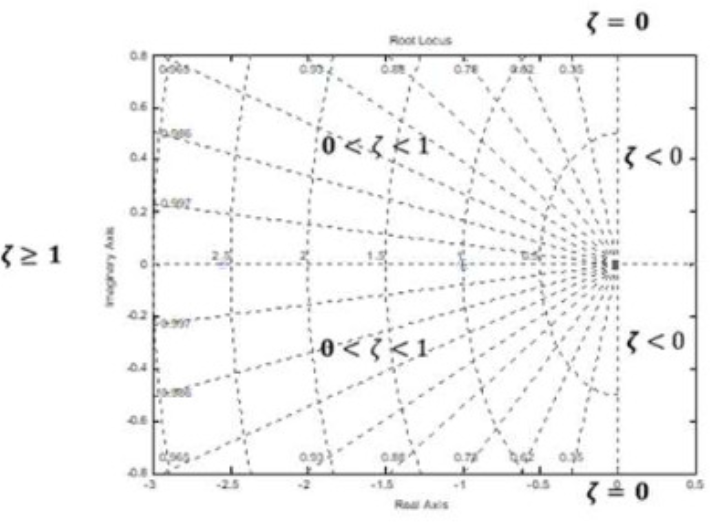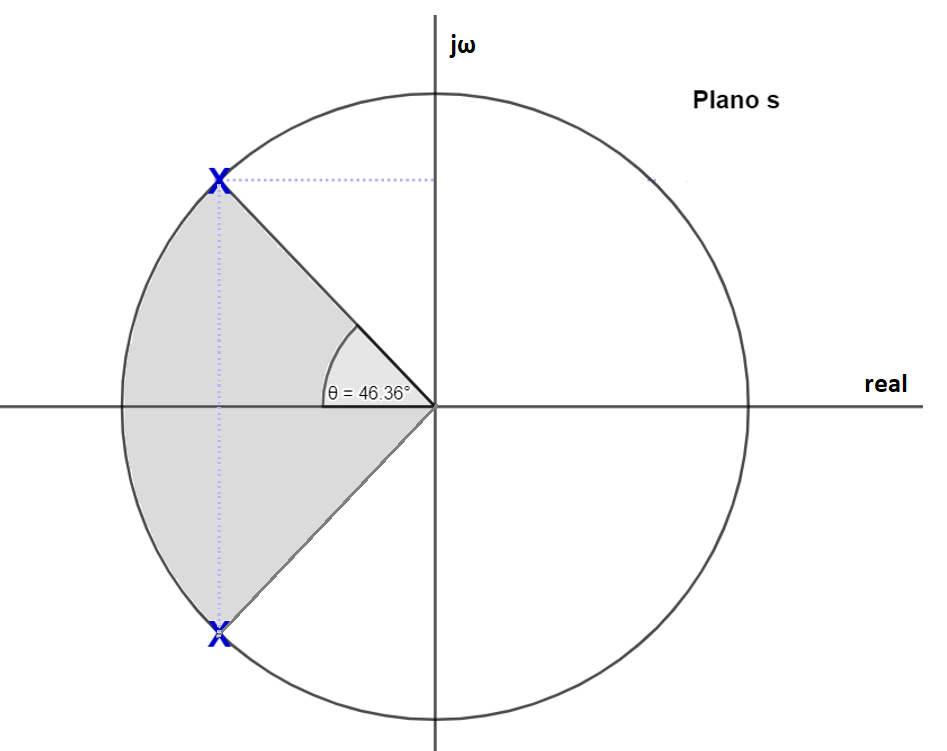

7) A figura 6 mostra a resposta ao impulso do sistema de segunda ordem do item 3. Explique como obter a resposta ao impulso a partir de G(s) usando a transformada de Laplace.

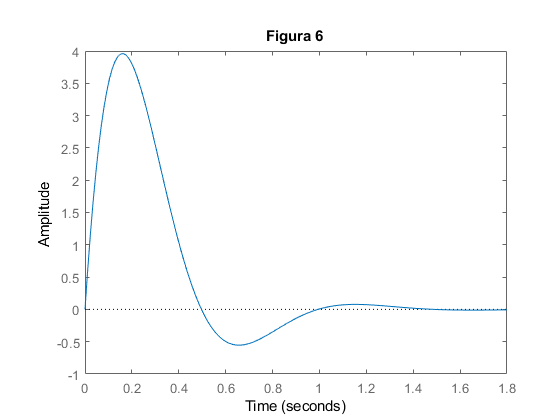

figure;impulse(g2);title('Figura 6')

Resposta:

Partindo do pressuposto de que **o sistema é linear e invariante no tempo**, podemos obter a resposta ao impulso a partir de G(s), usando a transformada de Laplace. Basta seguir o passo a passo abaixo:

- Definir a função de transferência G(s) do sistema, que nesse caso é $G_2$(s) =  $\frac{{\omega_n }^2 }{s^2 +2\zeta \omega_n s+{\omega_n }^2 }$ = $\frac{{7\ldotp 4615}^2 }{s^2 +2*0\ldotp 5308*7\ldotp 4615s+{7\ldotp 4615}^2 }$.

- Após isso, devemos aplicar um impulso unitário $\delta$(t) à entrada do sistema.

- Agora, encontramos a transformada de Laplace U(s) da entrada impulso $\delta$(t). Porém a trasformada do impulso é conhecida, sendo $L^{-1}$**{**$\delta$**(t)} = 1.**

- Calcula-se a transformada de Laplace da resposta do sistema y(s) para a entrada U(s) usando a função de transferência G(s). Porém, U(s) = 1, então, temos:

y(s) = G(s) * U(s)   $\to$    y(s) = G(s) * 1**    ∴    y(s) = G(s) **

- Para facilitar os cálculos subsequentes, devemos escrever a função de transferência G(s) na forma de soma de frações parciais, no seguinte formato:

**G(s) = **$\frac{K_1 }{\left(s-p_1 \right)}$** + **$\frac{K_2 }{\left(s-p_2 \right)}$** + **$\frac{K_3 }{\left(s-p_3 \right)}$** + .... + **$\frac{K_n }{\left(s-p_n \right)}$

- Com isso, calculamos a transformada inversa de Laplace de y(s) para obter a resposta ao impulso h(t) do sistema. 

  h(t) =$L^{-1}$**{G(s)} **

- Enfim, obtemos a resposta ao impulso de G(s) através da transformada de Laplace, para o intervalo de 0 $\le$ $\zeta$ $\le$ 1. 

sendo G(s) =  $\frac{{\omega_n }^2 }{s^2 +2\zeta \omega_n s+{\omega_n }^2 }$ ,        temos g(t) = $\frac{\omega_n }{\sqrt{1-\zeta^2 \;}}$$e^{-\zeta {\;\omega }_n \;t}$sen$\omega_n$$\sqrt{1-\zeta^2 \;}$t, para t $\ge$ 0.

8) Observe a resposta ao degrau do item 3) e escolha um tempo de amostragem de 10% do valor do tempo de estabilização medido. Discretize o modelo g2 usado com o comando c2d e plote no mesmo gráfico a resposta ao degrau dos sistemas contínuo e discreto.

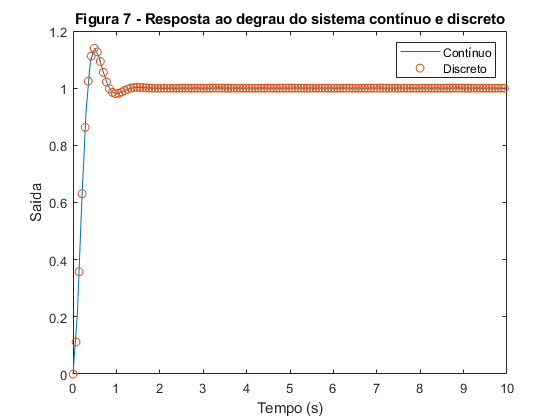

ts = 0.7;                               % tempo de estabilização do sistema, medido no item 3
t_amostragem = 0.1*ts;                  % tempo de amostragem de 10% do tempo de estabilização.
%---------------------------------------------- Sistema Contínuo ----------------------------------------------------------%

t = 0:0.1:10;                           % vetor de tempo de 0 a 10 segundos, com passo de 0.01s.
u = ones(size(t));                      % entrada degrau unitário com tamanho igual ao do vetor t.
y = lsim(g2,u,t);                       % resposta do sistema contínuo ao degrau.
            
%---------------------------------------------- Sistema Discreto ----------------------------------------------------------%

g2d = c2d(g2, t_amostragem, 'zoh');     % modelo discretizado usando o método ZOH (Hold zero-order)
td = 0:t_amostragem:10;                 % vetor de tempo discreto de 0 a 10 segundos, com passo igual ao tempo de amostragem
ud = ones(size(td));                    % entrada degrau unitário com tamanho igual ao do vetor td.
yd = lsim(g2d, ud, td);                 % resposta do sistema discreto ao degrau

%---------------------------------------------- Plotando o Gráfico ----------------------------------------------------------%
plot(t,y,'-', td,yd,'o')                % plotando ambos os gráficos juntos
legend('Contínuo','Discreto')          
xlabel('Tempo (s)')                     
ylabel('Saída')                         
title('Figura 7 - Resposta ao degrau do sistema contínuo e discreto')

9) Seja o sistema massa-mola-amortecedor mostrado na figura **8** e a equação diferencial que gere seu comportamento. $X$é o deslocamento em metros e $F$a força aplicada em Newtons.


$$m\ddot{x}+b\dot{x}+kx=f(t)$$


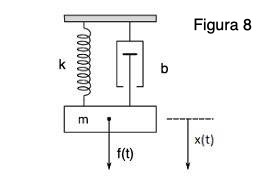

 Obtenha a função de transferência $G\left(s\right)=\frac{X\left(s\right)}{F\left(s\right)}$ e faça sua simulação ao degrau com os parâmetros M,K,B definidos abaixo. Qual o deslocamento máximo da massa e qual seu tempo de estabelecimento?

Resposta:

$\frac{X\left(s\right)}{F\left(s\right)}$ = $G\left(s\right)$ = $\frac{1}{Ms^2 +\textrm{Bs}+k}$

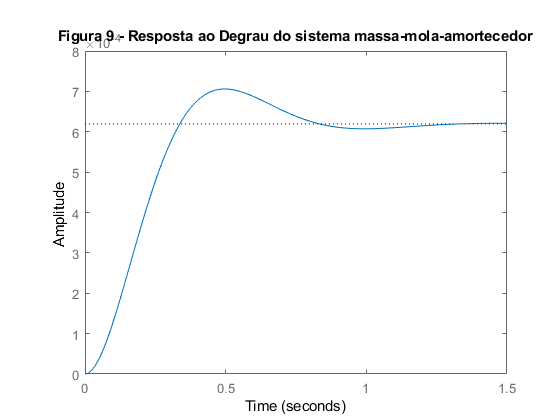

M=I;
K=M*wn^2;
B1=2*M*zeta*wn; % Aqui precisei renomear a variável de B para B1, para que não dê problema com a matriz da questão sobre variáveis de estado, cujo nome também é B. 
g = tf(1, [M B1 K]);
step(g)
title('Figura 9 - Resposta ao Degrau do sistema massa-mola-amortecedor');

Com a aplicação de uma força de 1 N (aplicou-se entrada ao degrau no sistema), foi gerado o gráfico da figura 9, onde podemos tirar as seguintes conclusôes:

 **- Deslocamento máximo:**

    O deslocamento da massa com a resposta ao degrau é observado no gráfico da figura 9 como a amplitude da saída.  O deslocamento máximo pode ser dito como o valor da amplitude máxima da saída, assim sendo, o deslocamento máximo é de 7.059 x ${10}^{-4}$ m, como marcado no gráfico.

**- Tempo de estabelecimento: **

    O sistema massa-mola é de 2° ordem, sendo assim, o tempo de estabilização é o tempo necessário para que a resposta se estabilize dentro de uma faixa específica, nesse caso de 5% em torno do valor final. Como o valor final da resposta é 6,211 x ${10}^{-4}$ , a faixa está entre 5,900 x ${10}^{-4}$ e 6,521 x ${10}^{-4}$. 

Com essas condições e analisando o gráfico, temos que **ts = 0.77s**.

*obs: nessa questão tentei deixar marcado o ponto no gráfico, porém estava dando erro no código, por isso não está marcado.*

10) Seja o diagrama de blocos mostrado abaixo.

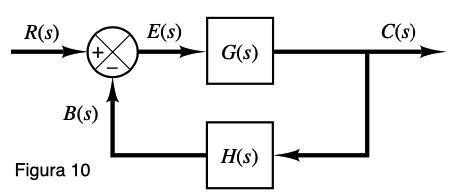

Obtenha:

$\frac{E\left(s\right)}{R\left(s\right)}$  $\to$ Sabemos que **E(s) = R(s) - B(s)**,  **B(s) = C(s)H(s)** e **C(s) = E(s)G(s)**. 

Assim, $E\left(s\right)$ = $R\left(s\right)$ - $C\left(s\right)H\left(s\right)$ $\therefore$ $E\left(s\right)$ = $R\left(s\right)$ - $E\left(s\right)G\left(s\right)H\left(s\right)$      

Organizando os termos, temos que   $E\left(s\right)$[1 + $G\left(s\right)H\left(s\right)$] = $R\left(s\right)$

Passando $R\left(s\right)$ para o lado esquerdo e [1 + $G\left(s\right)H\left(s\right)$] para o lado direito, ambos dividindo, concluímos que: 

$\frac{E\left(s\right)}{R\left(s\right)}$ = $\frac{1}{1+G\left(s\right)H\left(s\right)}$ 

$\frac{C\left(s\right)}{R\left(s\right)}$  $\to$ Temos que **C(s) = E(s)G(s)**,   **R(s) = E(s) + B(s)**   e   **B(s) = C(s)H(s).** 

Então $\frac{C\left(s\right)}{R\left(s\right)}$ = $\frac{E\left(s\right)G\left(s\right)}{E\left(s\right)+B\left(s\right)}$        

como **B(s) = C(s)H(s)**, temos: $\frac{C\left(s\right)}{R\left(s\right)}$ = $\frac{E\left(s\right)G\left(s\right)}{E\left(s\right)+C\left(s\right)H\left(s\right)}$   $\to$ mas ***C(s) = E(s)G(s)***, então:  $\frac{C\left(s\right)}{R\left(s\right)}$ = $\frac{E\left(s\right)G\left(s\right)}{E\left(s\right)+E\left(s\right)G\left(s\right)H\left(s\right)}$

isolando E(s), temos:       $\frac{E\left(s\right)}{E\left(s\right)}$* $\frac{G\left(s\right)}{1+1G\left(s\right)H\left(s\right)}$   

$\therefore$  $\frac{C\left(s\right)}{R\left(s\right)}$** = **$\frac{G\left(s\right)}{1+G\left(s\right)H\left(s\right)}$

11) Seja o sistema massa-mola-amortecedor do item **9**. Obtenha o modelo em variáveis de estado definido pelas matrizes [A,B,C,D] de modo que $x_1 \left(t\right)$ seja a posição e $x_2 \left(t\right)$seja a velocidade. Aplique então um degrau e plote os dois estados, explicando seu comportamento. Dica: veja o comando tf2ss.

sendo $x_1 \left(t\right)$ a posição da massa e $x_2 \left(t\right)$ a velocidade da massa, temos:

${x_1 }^{\prime } \left(t\right)$ = $x_2 \left(t\right)$ (***a derivada da posição é a velocidade***)

${x_2 }^{\prime } \left(t\right)$=     $\left(\frac{-\mathbf{B}}{\mathbf{M}}\right)$* $x_2 \left(t\right)$ + $\left(\frac{-\mathbf{K}}{\mathbf{M}}\right)$ * $x_1 \left(t\right)$ + $\left(\frac{1}{\mathbf{M}}\right)$* $u\left(t\right)$            

 $y\left(t\right)$ = [1 0] * [$x_1 \left(t\right)$; $x_2 \left(t\right)$]

onde $\mathit{\mathbf{u}}\left(\mathit{\mathbf{t}}\right)$ é a entrada do sistema (**força, em N, aplicada na massa**) e $\mathit{\mathbf{y}}\left(\mathit{\mathbf{t}}\right)$ é a saída do sistema (**posição da massa**).

Como pedido no enuciado, temos as Matrizes [A, B, C, D], sendo:

A  =  $\left\lbrack \frac{-\mathrm{K}\;}{\;\mathbf{M}}\;\frac{-\mathrm{B}\;}{\;\;\mathbf{M}};0\;\;1\right\rbrack$

B  =  $\left\lbrack 0\;\;\frac{1\;}{\;\mathbf{M}}\right\rbrack$

C  =  $\left\lbrack 1\;\;\;\;\;0\right\rbrack$

D  =  0

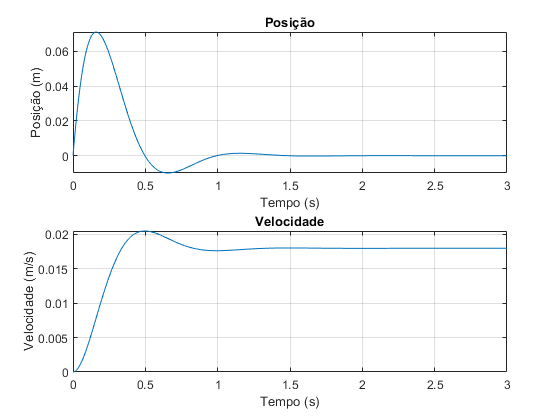

% Obtendo as matrizes para o modelo em variáveis de estado.
[A, B, C, D] = tf2ss(1, [M, B1, K]);

% Definindo o vetor de tempo e a entrada degrau
t = 0:0.01:3;
u = ones(size(t)); 

% Simulando a resposta do sistema
sys = ss(A, B, C, D);
x0 = [0; 0];
[y, t, x] = lsim(sys, u, t, x0);

% Plotando as variáveis de estado
subplot(2,1,1);
plot(t, x(:,1));
title('Posição');
xlabel('Tempo (s)');
ylabel('Posição (m)');
grid on;

subplot(2,1,2);
plot(t, x(:,2));
title('Velocidade');
xlabel('Tempo (s)');
ylabel('Velocidade (m/s)');
grid on;

A resposta do sistema pode ser analisada em relação à sua estabilidade e amortecimento. Se o sistema for estável, a massa irá oscilar em torno do ponto de equilíbrio sem aumentar ou diminuir a amplitude. Se for instável, a amplitude das oscilações aumentará com o tempo, afastando a massa do ponto de equilíbrio. Como podemos observar no gráfico, trata-se de um sistema estável, pois a massa oscila em torno do ponto de equilíbrio (posição = 0 m), tendendo para esse ponto à medida em que o tempo aumenta.

12) Seja gma definida abaixo.

gma=tf(wn^2*[1/p 1],[1 2*zeta*wn 0])

gma =
 
  4.64 s + 55.67
  --------------
  s^2 + 7.921 s
 
Continuous-time transfer function.



Obtenha seus polos e zeros de malha aberta e de malha fechada.

Resposta:

**Polos e Zeros de gma:**

% Obtendo os Polos de gma usando a função pole() do matlab.
pole(gma)

ans =          0
   -7.9207


% Obtendo os Zeros de gma usando a função zero() do matlab.
zero(gma)

ans = -12.0000

**Polos e Zeros de gmf:**

% Usando a função feedback para obter a gmf.
gmf = feedback(gma,1)

gmf =
 
     4.64 s + 55.67
  ---------------------
  s^2 + 12.56 s + 55.67
 
Continuous-time transfer function.



% Obtendo os Polos de gmf usando a função pole() do matlab.
pole(gmf)

ans =   -6.2801 + 4.0292i
  -6.2801 - 4.0292i


% Obtendo os Zeros de gmf usando a função zero() do matlab.
zero(gmf)

ans = -12.0000

Análise do erro em regime. Seja o diagrama de blocos mostrado abaixo com G(s) definida abaixo.

G=tf(p^2,poly(-[p p]));

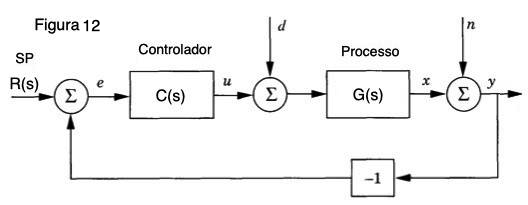

13) Qual o erro em regime para uma entrada degrau unitário caso $C\left(s\right)=K$?

Resposta:

**Entrada degrau unitário:  **$R\left(s\right)$ = $\frac{1}{s}$

Como consta no material de apoio, o erro em regime pode ser calculado da seguinte maneira:

$\frac{E\left(s\right)}{R\left(s\right)}$ = 1 - $\frac{C\left(s\right)}{R\left(s\right)}$, considerando $C\left(s\right)$ = k e a entrada $R\left(s\right)$ = $\frac{1}{s}$, temos que:

 $\frac{E\left(s\right)}{\frac{1}{s}}$ = 1 - $\frac{K}{\frac{1}{s}}$

 $E\left(s\right)$ = $\frac{1}{s}$ - $K$

O erro em regime é obtido pelo ***teorema do valor final***:

$\lim_{s\to 0} s\ldotp E\left(s\right)$  =   $\lim_{s\to 0} s\ldotp \left(\frac{1}{s}-K\right)$  =    $\lim_{s\to 0} 1$  -   $\lim_{s\to 0} \;\textrm{sK}$ = 1 - 0  ∴  $\lim_{s\to 0} s\ldotp E\left(s\right)$ = 1

**O Erro em regime para uma entrada degrau para caso **$C\left(s\right)=K$ **é 1**

14. Repita o item **13** para $C\left(s\right)=K_p +\frac{K_I }{s}$

Resposta:

**Entrada degrau unitário:  **$R\left(s\right)$ = $\frac{1}{s}$

Como consta no material de apoio, o erro em regime pode ser calculado da seguinte maneira:

$\frac{E\left(s\right)}{R\left(s\right)}$ = 1 - $\frac{C\left(s\right)}{R\left(s\right)}$, considerando $C\left(s\right)$ = $K_p +\frac{K_I }{s}$ e a entrada $R\left(s\right)$ = $\frac{1}{s}$, temos que:

 $\frac{E\left(s\right)}{\frac{1}{s}}$ = 1 - $\frac{K_p +\frac{K_I }{s}}{\frac{1}{s}}$      $\to$    $\frac{E\left(s\right)}{\frac{1}{s}}$ = 1 - $K_p \ldotp s-K_I$

 $E\left(s\right)$ = $\frac{1}{s}$ - $K_p -\frac{K_I }{s}$

O erro em regime é obtido pelo ***teorema do valor fina****l*:

$\lim_{s\to 0} s\ldotp E\left(s\right)$  =   $\lim_{s\to 0} s\ldotp \left(\frac{1}{s}-K_p -\frac{K_I }{s}\right)$  =    $\lim_{s\to 0} 1$  -   $\lim_{s\to 0} \;sK_p$ -   $\lim_{s\to 0} \;K_I$ =  1 - $0$ - $K_I$   ∴  $\lim_{s\to 0} s\ldotp E\left(s\right)=1-\mathrm{Ki}$

**Assim como no item anterior, para **$C\left(s\right)$ = $K_p +\frac{K_I }{s}$**, o erro em regime também é 1-Ki**

15. Caso um distúrbio $d\left(t\right)=1$ afete a malha de controle, como verificar seu efeito no erro E(s) para um dado controlador C(s)?

Ilustre aplicando o degrau em $d\left(t\right)=1$e plotando $y(t)$, com $r(t)=0$. Use $C(s)=K$, onde K garante estabilidade.

Resposta:

Para verificar o efeito do distúrbio $d\left(t\right)=1$ na malha de controle, temos que analisar o comportamento do erro $E\left(s\right)$ na presença desse distúrbio. Do material de apoio e dos estudos em AMSD, sabemos que o erro é definido como a diferença entre o sinal de entrada $r\left(t\right)$ e o sinal de saída do sistema $y\left(t\right)$. Nesse caso, o sinal de entrada é zero ($r\left(t\right)$ = 0), portanto o erro é igual a -y(t), $e\left(t\right)=-y\left(t\right)$.

Usando $C\left(s\right)$ = K, podemos determinar a função de transferência da malha fechada $G\left(s\right)$ como  $G\left(s\right)=\frac{C\left(s\right)}{1\;+C\left(s\right)G_p \left(s\right)}$. Onde $G_p \left(s\right)$ é a função de transferência do processo. 

Como o controlador é proporcional $C\left(s\right)=K$, a função de transferência do controlador $C\left(s\right)$ é simplesmente K. Assumindo que o sistema é estável, podemos determinar o valor de K que garante estabilidade, **K = 1.5**.

Para ilustrar o efeito do distúrbio $d\left(t\right)=1$, podemos simular a resposta do sistema com o código abaixo. 

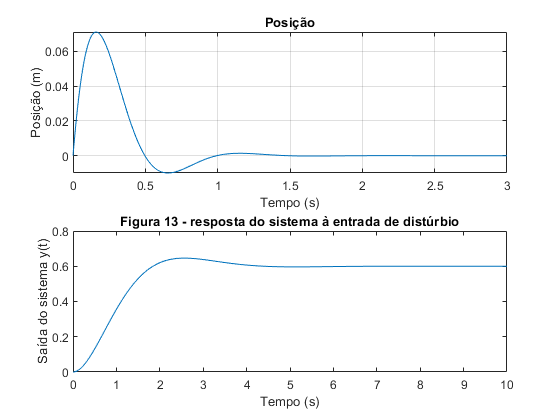

Gp = tf([1],[1 2 1]);           % Função de transferência Gp(s) do processo.
K = 1.5;                        % Ganho K do controlador.
G = feedback(K*Gp,1);           % Aqui usamos a função feedback para criar a malha fechada a partir de G(s)

t = 0:0.01:10;                  % vetor de tempo de o a 10 segundos com passo de 0.01s
d = ones(size(t));              % sinal de degrau para o distúrbio d(t) = 1.
r = zeros(size(t));             % sinal de entrada r(t) = 0.
[y,t] = lsim(G,d,t,r);          % simulação da resposta do sistema

plot(t,y);                      % plotando a resposta do sistema.
title('Figura 13 - resposta do sistema à entrada de distúrbio')
xlabel('Tempo (s)');
ylabel('Saída do sistema y(t)');

O resultado da simulação foi um gráfico que mostra a resposta do sistema à entrada de distúrbio. Observa-se que a presença do distúrbio causa um aumento no valor da saída do sistema, indicando que o erro do sistema aumentou (em módulo), pois $e\left(t\right)=-y\left(t\right)$, ou seja, esse é o efeito do distúrbio no erro do sistema para $C\left(s\right)=k$.

16. Verifique os valores de K para estabilidade de $\frac{Y(s)}{R(s)}=\frac{KG_3(s)}{1+KG_3(s)$ (g3 foi definida em init).

Resposta:

Para verificar os valores de k para estabilidade de $\frac{Y(s)}{R(s)}=\frac{KG_3(s)}{1+KG_3(s)$, podemos usar o **critério de estabilidade de Routh-Hurwitz**, seguindo o passo a passo abaixo:

**- Determinar a equação característica:**

    A equação característica é o denominador da FTMF, sendo 1 + k$G_3 \left(s\right)$ e devemos igualar a 0, ficando: 1 + k$G_3 \left(s\right)$ = 0

**- Função **${\mathit{\mathbf{G}}}_3 \left(\mathit{\mathbf{s}}\right)$**:**

g3

g3 =
 
             1728
  ---------------------------
  s^3 + 36 s^2 + 432 s + 1728
 
Continuous-time transfer function.



**- Então, temos a equação característica:**

    1 + $\frac{k\ldotp 1728}{s^3 \;+\;36s^2 \;+\;432s\;+\;1728}$ = 0

**- Resolvendo os termos, temos:**

  
$$s^3 \;+\;36s^2 \;+\;432s\;+\;1728+k\ldotp 1728\;=\;0$$
      
$$\to$$
   
$$s^3 \;+\;36s^2 \;+\;432s\;+\;1728\left(1+k\right)\;=\;0$$


**- Agora, chegamos ao polinômio em s da seguinte maneira: **

$a_0 s^n \;+a_1 s^{n-1} \;\ldotp \ldotp \ldotp +a_{n-1} s\;+a_n \;=0\;$ **onde  **n = 3 e $a_0 =1\;\;;{\;a}_1 =36\;\;;a_2 =432\;\;\;e\;\;a_3 \;=1728\left(1+k\right)\;$ 

**- Assim, podemos montar a tabela para aplicar o critério de estabilidade de Routh-Hurwitz:**

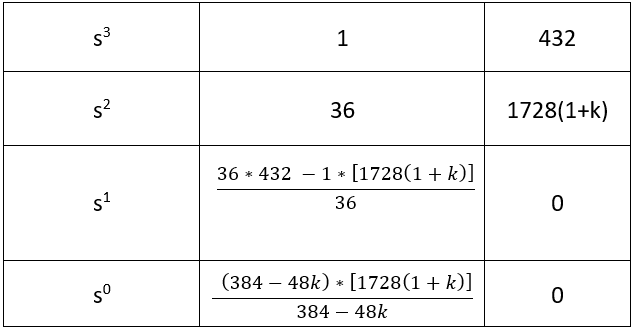 simplificando $\to$ 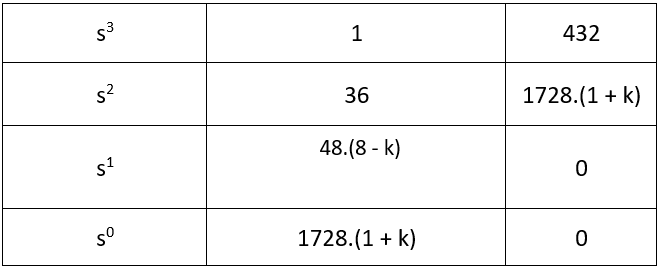

Para que o sistema seja **estável**, os valores de da 2° coluna da tabela acima da direita não podem mudar de sinal, pois o número de raízes com parte real positiva é igual ao númeor de mudanças de sinal na 2° coluna, e se o sistema tiver raíz com parte real positiva, ele está à direita do eixo j$\omega$, ou seja, sistema instável. 

Para que não haja mudanças de sinal na 2° coluna e o sistema seja estável, temos 2 condições:

**1°** $\to$ 48(8 - k) $>$ 0, ou seja k $<$ 8

**2° **$\to$ 1728(1 + k) $>$ 0; ou seja, k $>$ - 1

Então, considerando apenas ganho positivo **(k**$>$**0)**, os valores de k para que o sistema seja estável está no intervalo **0 **$<$** k **$<$** 8.**